# 1. Извлечение гармоник из спектра

## Красницкий Никита

Задача: получить значения амплитуд и частот гармоник из общего спектра звука.

В пункте 1.1 созданы общие вектора и константы. Тут они подгружаются

clear all
close all
load('1.Load Data.mat');

Исследуемый звук

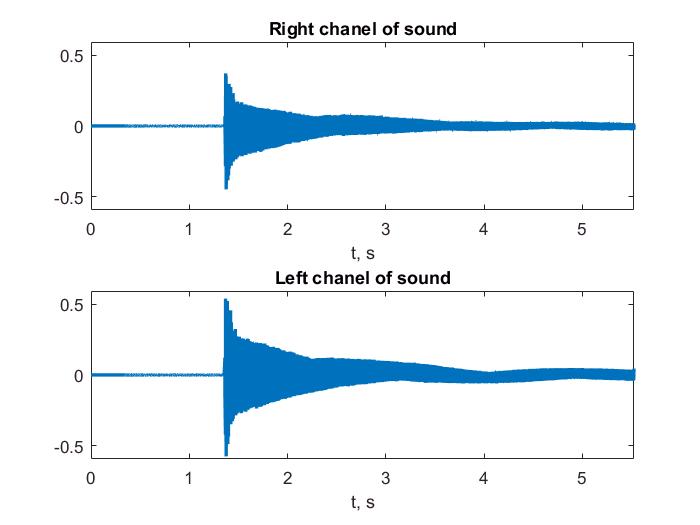

%sound(x, fs);
M = 1.1 * max(max(x));

figure
subplot(2,1,1);
plot(t, x(:,1), 'LineWidth', 2);     
ylim([-M M]);
xlim([0 t(end)]);
title('Right chanel of sound');
xlabel('t, s');

subplot(2,1,2);
plot(t, x(:,2), 'LineWidth', 2); 
ylim([-M M]);
xlim([0 t(end)]);
title('Left chanel of sound');
xlabel('t, s');

## Спектры

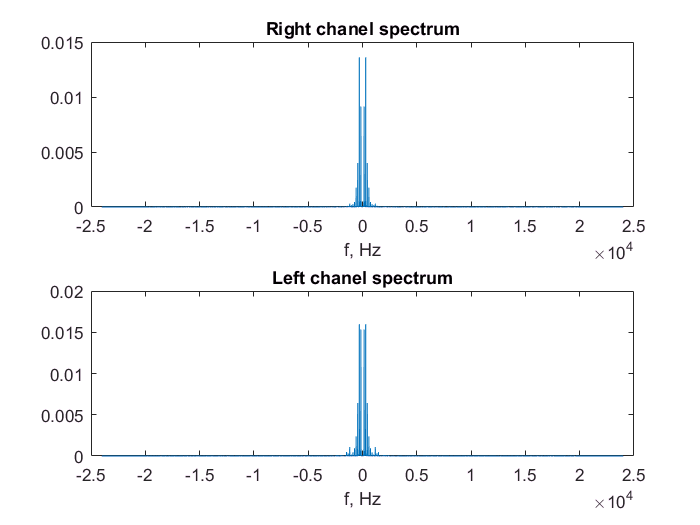

X(:,1) = fft(x(:,1)) / N;
X(:,2) = fft(x(:,2)) / N;

figure
subplot(2,1,1);
plot(f, abs(fftshift(X(:,1))));
title('Right chanel spectrum');
xlabel('f, Hz');

subplot(2,1,2);
plot(f, abs(fftshift(X(:,2))));
title('Left chanel spectrum');
xlabel('f, Hz');

Нахождение гармоник спектра. Для этого достаточно иметь только положительные частоты спектра, для чего введены новые вектора Xp и fp. Поскольку нота ДО большой октавы соответствует колебанию в 65Гц и оно принято за самое низкое из рассматриваемых, то пики спектра должны находится на расстоянии не меньше 60ти Герц. Минимальной амплитудой гармоники считается амплитуда более одной сотой от гармоники с максимальной амплитудой.

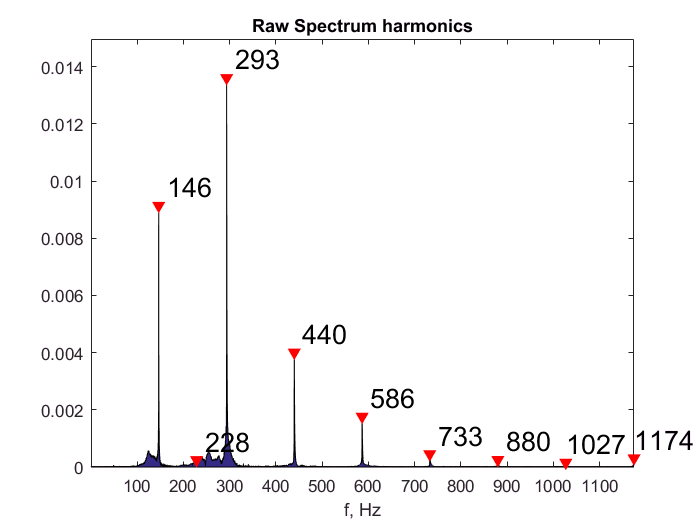

Xp = abs(fftshift(X(:,1)));
Xp = Xp(N/2 + 1:end);
fp = f(N/2 + 1:end);
MinFreqStep = 60;
MinAmplitude = max(max(Xp)) / 100;

[pksRaw, FharmRaw] = findpeaks(Xp, fp, 'MinPeakDistance', MinFreqStep...
                          ,'MinPeakHeight', MinAmplitude);

figure
area(fp, Xp);
hold on
plot(FharmRaw, pksRaw, 'rv', 'MarkerFaceColor', 'r');
yScaleAdd = max(pksRaw)*0.05; 
cellpeaks = cellstr(num2str(round(FharmRaw', 0)));
text(FharmRaw, yScaleAdd+pksRaw, cellpeaks, 'FontSize', 16);
ylim([0 max(pksRaw)+2*yScaleAdd]);
xlim([fp(1) FharmRaw(end)])
hold off
title('Raw Spectrum harmonics');
xlabel('f, Hz');

Отсеиваются случайные ошибки на основе принципа кратности частот гармоник.

## В будущем нужно добавить поиск основного тона, т.к. первая гармоника тоде может быть ошибочной!

F0 = FharmRaw(1);
ErrorThreshold = 0.05;
FharmCnt = 0;
Fharm    = 0;
pks      = 0;

for i = 1:length(FharmRaw)
    integerVal = floor(FharmRaw(i)/F0);
    floatVal   = FharmRaw(i)/F0;
    freqDifference = abs(floatVal-integerVal);
    if ( freqDifference < ErrorThreshold )
        FharmCnt = FharmCnt+1;
        Fharm(FharmCnt) = FharmRaw(i);
        pks(FharmCnt) = pksRaw(i);
    end
end

freqDifference = 0

freqDifference = 0.5600

freqDifference = 0.0037

freqDifference = 0.0025

freqDifference = 0.0049

freqDifference = 0.0037

freqDifference = 0.0099

freqDifference = 0.0136

freqDifference = 0.0210

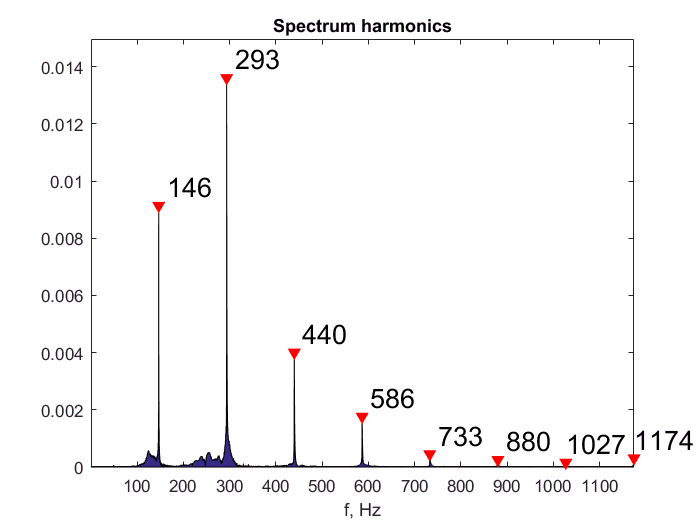


figure
area(fp, Xp);
hold on
plot(Fharm, pks, 'rv', 'MarkerFaceColor', 'r');
yScaleAdd = max(pks)*0.05; 
cellpeaks = cellstr(num2str(round(Fharm', 0)));
text(Fharm, yScaleAdd+pks, cellpeaks, 'FontSize', 16);
ylim([0 max(pks)+2*yScaleAdd]);
xlim([fp(1) Fharm(end)])
hold off
title('Spectrum harmonics');
xlabel('f, Hz');

Данные о частотах гармоник и их амплитудах сохраняются для дальнейшего использования

fileName = '1.Harmonics Frequencies.mat';
save(fileName, 'Fharm', 'pks');